%Parámetros DH

ai = [0, -97.4, 98.2, 0];
alphai = [deg2rad(-90), deg2rad(0), deg2rad(0), deg2rad(-90)];
di = [0, 0, 0, 0];
thetai = {'q1*', 'q2*', 'q3*', 'q4*'};
offset = [deg2rad(0), deg2rad(90), deg2rad(-90), deg2rad(-90)];
table(ai',alphai',di',thetai',offset','VariableNames',{'a (mm)','alpha (rad)','d (mm)','theta (rad)', 'Offset (°)'})

ans = 4×5 table
    a (mm)    alpha (rad)    d (mm)    theta (rad)    Offset (°)
    ______    ___________    ______    ___________    __________

        0       -1.5708        0         {'q1*'}             0  
    -97.4             0        0         {'q2*'}        1.5708  
     98.2             0        0         {'q3*'}       -1.5708  
        0       -1.5708        0         {'q4*'}       -1.5708  


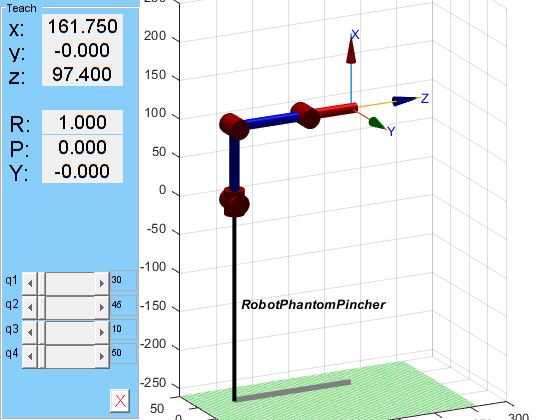

%Diagrama Robot

q = sym('q', [1 4]);
L(1) = Link('revolute','alpha',alphai(1),'a',ai(1),'d',di(1),'offset',offset(1),'qlim',[deg2rad(30) deg2rad(230)]);
L(2) = Link('revolute','alpha',alphai(2),'a',ai(2),'d',di(2),'offset',offset(2),'qlim',[deg2rad(45) deg2rad(255)]);
L(3) = Link('revolute','alpha',alphai(3),'a',ai(3),'d',di(3),'offset',offset(3),'qlim',[deg2rad(10) deg2rad(280)]);
L(4) = Link('revolute','alpha',alphai(4),'a',ai(4),'d',di(4),'offset',offset(4),'qlim',[deg2rad(50) deg2rad(240)]);
Tool = [1 0 0 0; 0 1 0 0; 0 0 1 63.55; 0 0 0 1];
World = eye(4);
RobotPhantom = SerialLink(L,'name','RobotPhantomPincher','tool',Tool,'base',World);
RobotPhantom.plot([0 0 0 0],'view',[-27 18]);
axis([-50 300 -150 50 -260 250]);
RobotPhantom.teach();

%Matriz de transformación homogénea desde la base hasta el efector final

MTH04 = RobotPhantom.fkine(q) %Cinemática directa del sistema 4 con respecto al sistema 0.

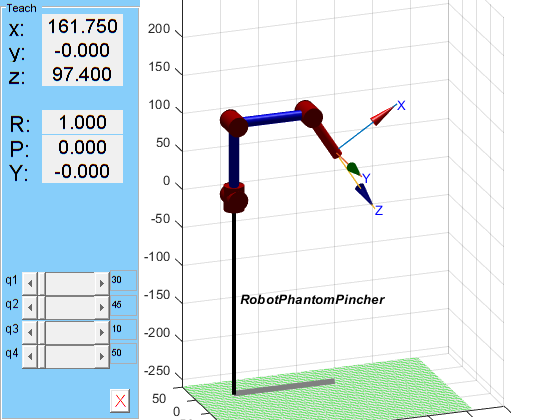

%Posiciones del robot

% RobotPhantom.plot([0 0 0 0],'view',[-20 20]); %Posición Home
% axis([-50 300 -150 50 -260 250]);

% RobotPhantom.plot([1 0 0 0],'view',[-20 20]); %Posición 1
% axis([-50 300 -150 250 -260 250]);

% RobotPhantom.plot([0 1 0 0],'view',[-20 20]); %Posición 2
% axis([-50 300 -150 50 -260 250]);

% RobotPhantom.plot([0 0 1 0],'view',[-20 20]); %Posición 3
% axis([-50 300 -150 50 -260 250]);

RobotPhantom.plot([0 0 0 1],'view',[-20 20]); %Posición 4
axis([-50 300 -150 50 -260 250]);